# Spikes vs Excitatory and Inhibitory Currents for the Moving Bar stimulus

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

us = {};
ds = {};

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
priorityOrder_2b = {'Extracellular'};
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Inhibition'};
mustHave_2c = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upSpikesPD = [];
upSpikesND = [];
upSpikesDSIs = [];
upInhibitionPeakPD = [];
upInhibitionChargePD = [];
upInhibitionPeakND = [];
upInhibitionChargeND = [];
upExcitationPeakPD = [];
upExcitationChargePD = [];
upExcitationPeakND = [];
upExcitationChargeND = [];
PD = 90;
ND = 270;
%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_inhibition, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_excitation, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2c, cantHave_2, rigMandates);
    [loc_spikes, pass3] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2 || pass3
        continue
    end
    us(end + 1) = {struct_i.cellID};
    PD_index = loc_spikes.Analysis_Results.Orientation == PD;
    ND_index = loc_spikes.Analysis_Results.Orientation == ND;
    upSpikesPD(end + 1) = loc_spikes.Analysis_Results.mean_spikesByOrientation(PD_index);
    upSpikesND(end + 1) = loc_spikes.Analysis_Results.mean_spikesByOrientation(ND_index);
    upSpikesDSIs(end + 1) = loc_spikes.Analysis_Results.DSI;
    
    PD_EpochNums = loc_inhibition.Analysis_Results.orientationByEpoch == PD;
    ND_EpochNums = loc_inhibition.Analysis_Results.orientationByEpoch == ND;
    upInhibitionPeakPD(end + 1) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(PD_EpochNums));
    upInhibitionPeakND(end + 1) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(ND_EpochNums));
    upInhibitionChargePD(end + 1) = mean(loc_inhibition.Analysis_Results.TotalChargeByEpoch(PD_EpochNums));
    upInhibitionChargeND(end + 1) = mean(loc_inhibition.Analysis_Results.TotalChargeByEpoch(ND_EpochNums));
    
    PD_EpochNums = loc_excitation.Analysis_Results.orientationByEpoch == PD;
    ND_EpochNums = loc_excitation.Analysis_Results.orientationByEpoch == ND;
    upExcitationPeakPD(end + 1) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(PD_EpochNums));
    upExcitationPeakND(end + 1) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(ND_EpochNums));
    upExcitationChargePD(end + 1) = -mean(loc_excitation.Analysis_Results.TotalChargeByEpoch(PD_EpochNums));
    upExcitationChargeND(end + 1) = -mean(loc_excitation.Analysis_Results.TotalChargeByEpoch(ND_EpochNums));
end


downSpikesPD = [];
downSpikesND = [];
downSpikesDSIs = [];
downInhibitionPeakPD = [];
downInhibitionChargePD = [];
downInhibitionPeakND = [];
downInhibitionChargeND = [];
downExcitationPeakPD = [];
downExcitationChargePD = [];
downExcitationPeakND = [];
downExcitationChargeND = [];
PD = 270;
ND = 90;
%downs second
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_inhibition, pass1] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_excitation, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2c, cantHave_2, rigMandates);
    [loc_spikes, pass3] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2b, mustHave_2b, cantHave_2, rigMandates);
    if pass1 || pass2 || pass3
        continue
    end
    us(end + 1) = {struct_i.cellID};
    PD_index = loc_spikes.Analysis_Results.Orientation == PD;
    ND_index = loc_spikes.Analysis_Results.Orientation == ND;
    downSpikesPD(end + 1) = loc_spikes.Analysis_Results.mean_spikesByOrientation(PD_index);
    downSpikesND(end + 1) = loc_spikes.Analysis_Results.mean_spikesByOrientation(ND_index);
    downSpikesDSIs(end + 1) = loc_spikes.Analysis_Results.DSI;

    PD_EpochNums = loc_inhibition.Analysis_Results.orientationByEpoch == PD;
    ND_EpochNums = loc_inhibition.Analysis_Results.orientationByEpoch == ND;
    downInhibitionPeakPD(end + 1) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(PD_EpochNums));
    downInhibitionPeakND(end + 1) = mean(loc_inhibition.Analysis_Results.maxPositivePeakByEpoch(ND_EpochNums));
    downInhibitionChargePD(end + 1) = mean(loc_inhibition.Analysis_Results.TotalChargeByEpoch(PD_EpochNums));
    downInhibitionChargeND(end + 1) = mean(loc_inhibition.Analysis_Results.TotalChargeByEpoch(ND_EpochNums));
    
    PD_EpochNums = loc_excitation.Analysis_Results.orientationByEpoch == PD;
    ND_EpochNums = loc_excitation.Analysis_Results.orientationByEpoch == ND;
    downExcitationPeakPD(end + 1) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(PD_EpochNums));
    downExcitationPeakND(end + 1) = mean(loc_excitation.Analysis_Results.maxNegativePeakByEpoch(ND_EpochNums));
    downExcitationChargePD(end + 1) = -mean(loc_excitation.Analysis_Results.TotalChargeByEpoch(PD_EpochNums));
    downExcitationChargeND(end + 1) = -mean(loc_excitation.Analysis_Results.TotalChargeByEpoch(ND_EpochNums));
end


## Peak Current vs Spikes

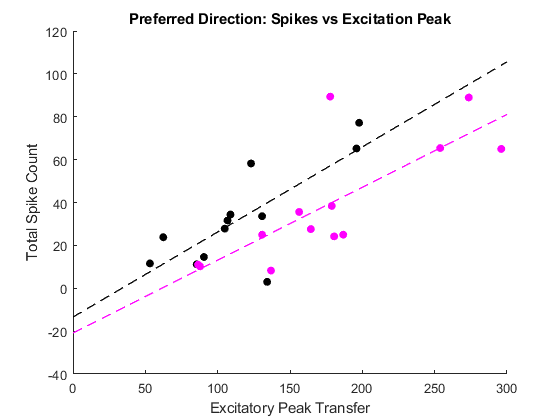

mdlUp = fitlm(-upExcitationPeakPD, upSpikesPD);
mdlDown = fitlm(-downExcitationPeakPD, downSpikesPD);

fitQueries = [0:100:300];

upMdlPredictions = feval(mdlUp, fitQueries);
downMdlPredictions = feval(mdlDown, fitQueries);

figure
title('Preferred Direction: Spikes vs Excitation Peak')
hold on
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
scatter(-upExcitationPeakPD, upSpikesPD , 'k', 'filled')
scatter(-downExcitationPeakPD, downSpikesPD, 'm', 'filled')
xlabel('Excitatory Peak Transfer')
ylabel('Total Spike Count')

[corrCoef, up_pval] = corr(-upExcitationPeakPD', upSpikesPD', 'type', 'Spearman')

corrCoef = 0.6294

up_pval = 0.0324

[corrCoef, down_pval] = corr(-downExcitationPeakPD', downSpikesPD', 'type', 'Spearman')

corrCoef = 0.6685

down_pval = 0.0125

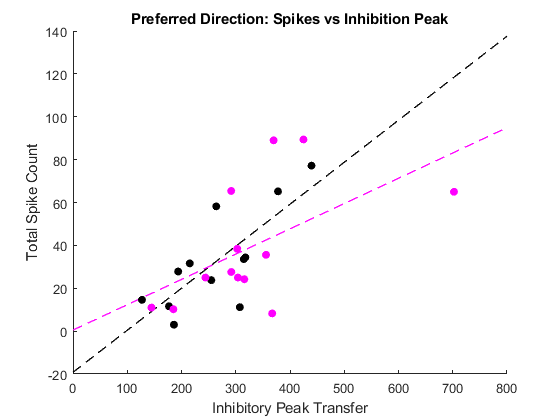

mdlUp = fitlm(upInhibitionPeakPD, upSpikesPD);
mdlDown = fitlm(downInhibitionPeakPD, downSpikesPD);

fitQueries = [0:100:800];

upMdlPredictions = feval(mdlUp, fitQueries);
downMdlPredictions = feval(mdlDown, fitQueries);

figure
title('Preferred Direction: Spikes vs Inhibition Peak')
hold on
plot(fitQueries, upMdlPredictions, '--k', 'LineWidth', 1)
plot(fitQueries, downMdlPredictions, '--m', 'LineWidth', 1)
scatter(upInhibitionPeakPD, upSpikesPD , 'k', 'filled')
scatter(downInhibitionPeakPD, downSpikesPD, 'm', 'filled')
xlabel('Inhibitory Peak Transfer')
ylabel('Total Spike Count')

[corrCoef, up_pval] = corr(upInhibitionPeakPD', upSpikesPD', 'type', 'Spearman')

corrCoef = 0.7552

up_pval = 0.0066

[corrCoef, down_pval] = corr(downInhibitionPeakPD', downSpikesPD', 'type', 'Spearman')

corrCoef = 0.4952

down_pval = 0.0853

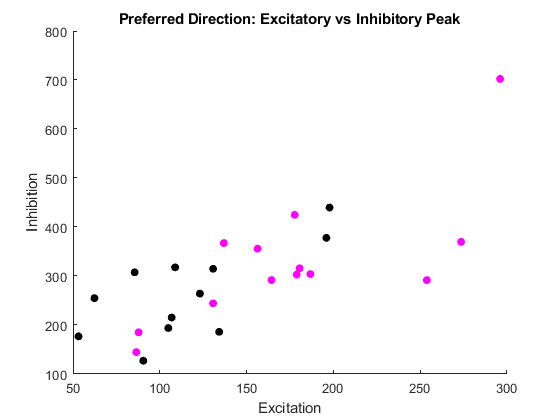


figure
title('Preferred Direction: Excitatory vs Inhibitory Peak')
hold on
scatter(-upExcitationPeakPD , upInhibitionPeakPD, 'k', 'filled')
scatter(-downExcitationPeakPD, downInhibitionPeakPD, 'm', 'filled')
xlabel('Excitation')
ylabel('Inhibition')

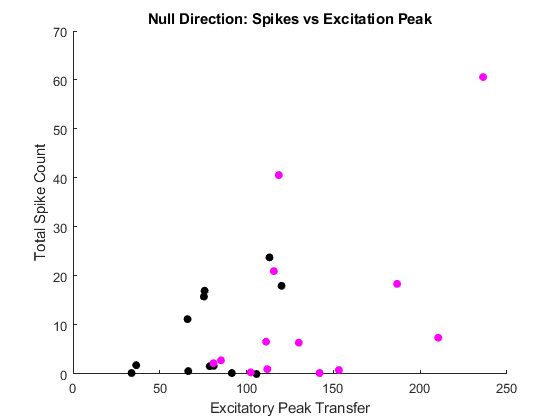


figure
title('Null Direction: Spikes vs Excitation Peak')
hold on
scatter(-upExcitationPeakND, upSpikesND , 'k', 'filled')
scatter(-downExcitationPeakND, downSpikesND, 'm', 'filled')
xlabel('Excitatory Peak Transfer')
ylabel('Total Spike Count')

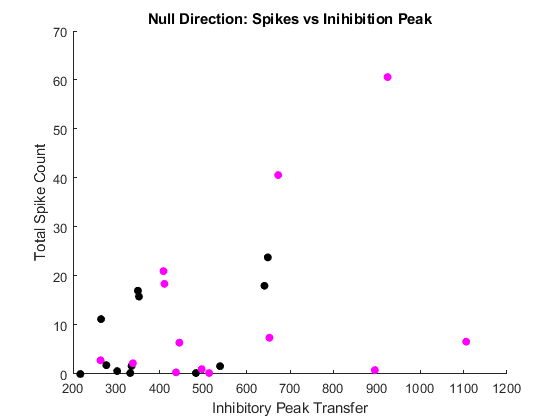

figure
title('Null Direction: Spikes vs Inihibition Peak')
hold on
scatter(upInhibitionPeakND, upSpikesND , 'k', 'filled')
scatter(downInhibitionPeakND, downSpikesND, 'm', 'filled')
xlabel('Inhibitory Peak Transfer')
ylabel('Total Spike Count')

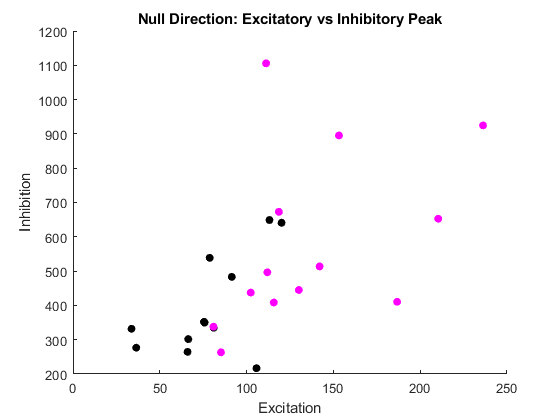

figure
title('Null Direction: Excitatory vs Inhibitory Peak')
hold on
scatter(-upExcitationPeakND , upInhibitionPeakND, 'k', 'filled')
scatter(-downExcitationPeakND, downInhibitionPeakND, 'm', 'filled')
xlabel('Excitation')
ylabel('Inhibition')

## Charge Vs Spikes

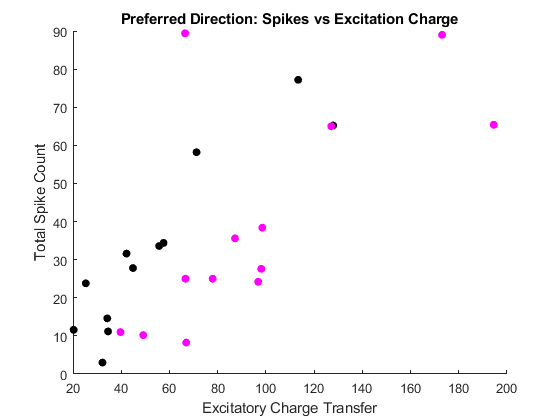


figure
title('Preferred Direction: Spikes vs Excitation Charge')
hold on
scatter(upExcitationChargePD, upSpikesPD , 'k', 'filled')
scatter(downExcitationChargePD, downSpikesPD, 'm', 'filled')
xlabel('Excitatory Charge Transfer')
ylabel('Total Spike Count')

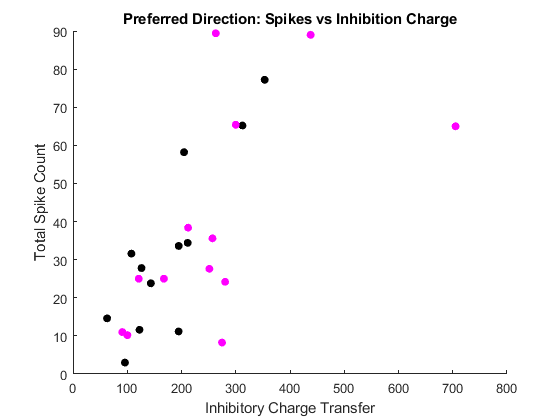

figure
title('Preferred Direction: Spikes vs Inhibition Charge')
hold on
scatter(upInhibitionChargePD, upSpikesPD , 'k', 'filled')
scatter(downInhibitionChargePD, downSpikesPD, 'm', 'filled')
xlabel('Inhibitory Charge Transfer')
ylabel('Total Spike Count')

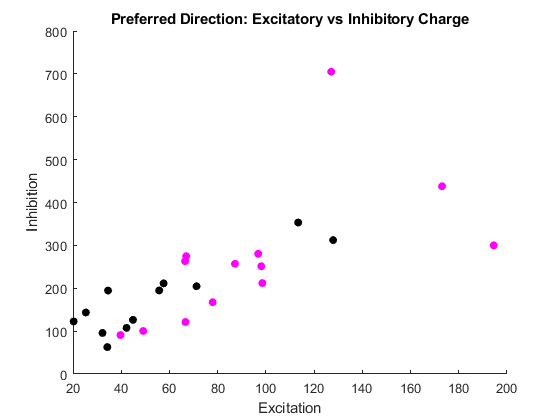

figure
title('Preferred Direction: Excitatory vs Inhibitory Charge')
hold on
scatter(upExcitationChargePD , upInhibitionChargePD, 'k', 'filled')
scatter(downExcitationChargePD, downInhibitionChargePD, 'm', 'filled')
xlabel('Excitation')
ylabel('Inhibition')

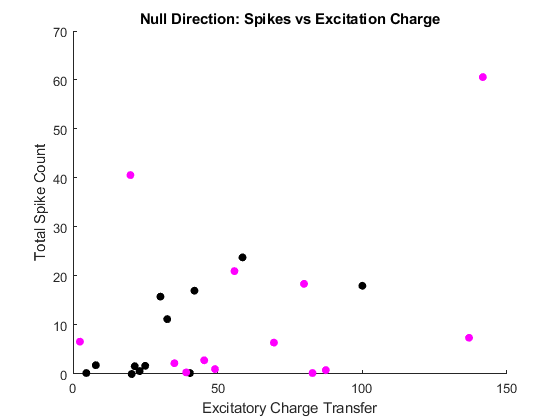


figure
title('Null Direction: Spikes vs Excitation Charge')
hold on
scatter(upExcitationChargeND, upSpikesND , 'k', 'filled')
scatter(downExcitationChargeND, downSpikesND, 'm', 'filled')
xlabel('Excitatory Charge Transfer')
ylabel('Total Spike Count')

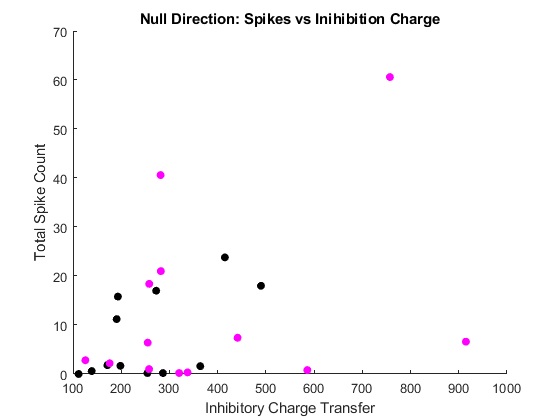

figure
title('Null Direction: Spikes vs Inihibition Charge')
hold on
scatter(upInhibitionChargeND, upSpikesND , 'k', 'filled')
scatter(downInhibitionChargeND, downSpikesND, 'm', 'filled')
xlabel('Inhibitory Charge Transfer')
ylabel('Total Spike Count')

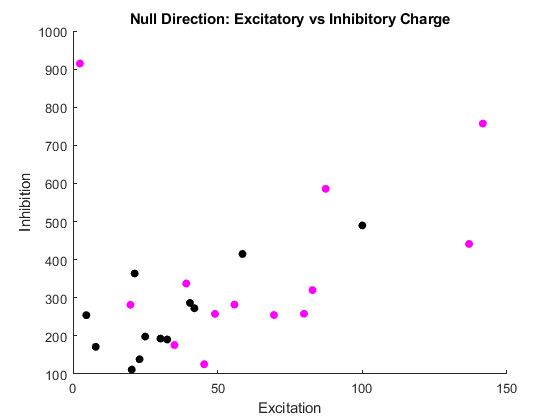

figure
title('Null Direction: Excitatory vs Inhibitory Charge')
hold on
scatter(upExcitationChargeND , upInhibitionChargeND, 'k', 'filled')
scatter(downExcitationChargeND, downInhibitionChargeND, 'm', 'filled')
xlabel('Excitation')
ylabel('Inhibition')